M = csvread('filtered_combined_eeg_df.csv')

M =          0   -1.7202
    0.0040   -0.5914
    0.0080    0.2018
    0.0120    0.4865
    0.0160    0.6578
    0.0200    1.0362
    0.0240    1.3293
    0.0280    1.1247
    0.0320    0.8052
    0.0360    1.3918


x = M(:,1)

x =          0
    0.0040
    0.0080
    0.0120
    0.0160
    0.0200
    0.0240
    0.0280
    0.0320
    0.0360


y = M(:,2)

y =    -1.7202
   -0.5914
    0.2018
    0.4865
    0.6578
    1.0362
    1.3293
    1.1247
    0.8052
    1.3918


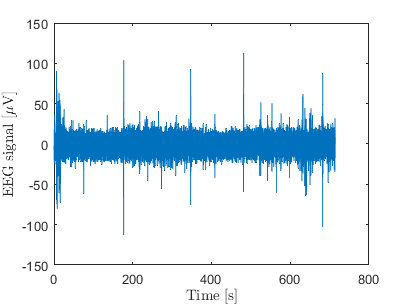

figure
plot(x,y)
xlabel("Time [s]", 'interpreter', 'latex')
ylabel("EEG signal [$\mu$V]", 'interpreter', 'latex')



M_easy = [M(44626:86762, 1), M(44626:86762, 2)]

M_easy =   178.5000   -8.3827
  178.5040   -6.4197
  178.5080   -2.4807
  178.5120    1.6477
  178.5160    5.0474
  178.5200    8.0502
  178.5240   11.4239
  178.5280   15.3185
  178.5320   19.0330
  178.5360   21.6156


M_hard = [M(86763:120366, 1), M(86763:120366, 2)]

M_hard =   347.0480   92.1501
  347.0520   56.2710
  347.0560   25.0776
  347.0600   27.4399
  347.0640   49.6344
  347.0680   64.5131
  347.0720   67.5193
  347.0760   70.3087
  347.0800   77.8695
  347.0840   84.6586


M_easy2 = [M(120366:170598, 1), M(120366:170598, 2)]

M_easy2 =   481.4600  112.5160
  481.4640   88.1274
  481.4680   19.3133
  481.4720  -43.7722
  481.4760  -56.2864
  481.4800  -19.3802
  481.4840   24.4855
  481.4880   37.3571
  481.4920   24.9015
  481.4960   22.3083



% Easy 1
Fs = 250; 
N = length(M_easy);
X = fft(M_easy(:,2));
P2 = abs(X/N).^2; % Two-sided PSD
P1 = P2(1:N/2+1); % Convert to a one-sided PSD

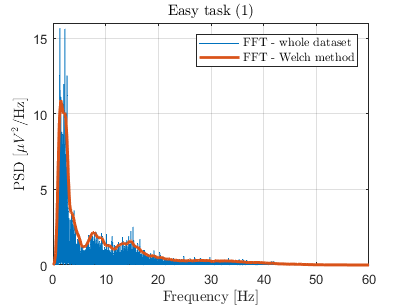


P1(2:end-1) = 2*P1(2:end-1); % drop negative frequencies

f = Fs*(0:(N/2))/N;

Fs = 250;           % Sampling frequency
window = 500;       % Window length (can be tuned as needed)
noverlap = 250;     % Overlap between segments
nfft = 1024;        % Number of FFT points (can be tuned as needed)

figure;
plot(f, P1*length(M_easy)/nfft) % Rescaling full-data FFT to match FFt calculated on shorter time intervals


hold on;
% Compute the PSD using Welch's method
[Pxx, f] = pwelch(M_easy(:,2), window, noverlap, nfft, Fs);
plot(f, Pxx, 'LineWidth', 2);

xlabel('Frequency [Hz]', 'interpreter', 'latex')
ylabel('PSD [$\mu V^2$/Hz]', 'interpreter', 'latex')
xlim([0, 60]);
grid on;

legend("FFT - whole dataset", "FFT - Welch method", 'interpreter', 'latex');
title("Easy task (1)", 'Interpreter','latex');



% Easy 2
Fs = 250; 
N = length(M_easy2);
X = fft(M_easy2(:,2));
P2 = abs(X/N).^2; % Two-sided PSD
P1 = P2(1:N/2+1); % Convert to a one-sided PSD

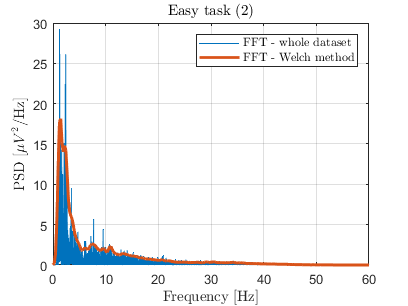



P1(2:end-1) = 2*P1(2:end-1); % drop negative frequencies

f = Fs*(0:(N/2))/N;

figure;
plot(f, P1*length(M_easy2)/nfft);  % Rescaling full-data FFT to match FFt calculated on shorter time intervals

hold on;
% Compute the PSD using Welch's method
[Pxx, f] = pwelch(M_easy2(:,2), window, noverlap, nfft, Fs);
plot(f, Pxx, 'LineWidth', 2);

xlabel('Frequency [Hz]', 'interpreter', 'latex')
ylabel('PSD [$\mu V^2$/Hz]', 'interpreter', 'latex')
xlim([0, 60]);
grid on;
legend("FFT - whole dataset", "FFT - Welch method", 'interpreter', 'latex');

title("Easy task (2)", 'Interpreter','latex');

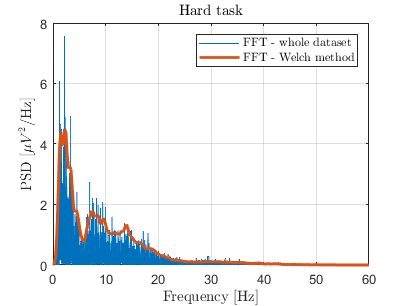


% Easy 2
Fs = 250; 
N = length(M_hard);
X = fft(M_hard(:,2));
P2 = abs(X/N).^2; % Two-sided PSD
P1 = P2(1:N/2+1); % Convert to a one-sided PSD


P1(2:end-1) = 2*P1(2:end-1); % drop negative frequencies

f = Fs*(0:(N/2))/N;

figure;
plot(f, P1*length(M_hard)/nfft)  % Rescaling full-data FFT to match FFt calculated on shorter time intervals
hold on;
% Compute the PSD using Welch's method
[Pxx, f] = pwelch(M_hard(:,2), window, noverlap, nfft, Fs);
plot(f, Pxx, 'LineWidth', 2);

xlabel('Frequency [Hz]', 'interpreter', 'latex')
ylabel('PSD [$\mu V^2$/Hz]', 'interpreter', 'latex')
xlim([0, 60]);
grid on;
legend("FFT - whole dataset", "FFT - Welch method", 'interpreter', 'latex');

title("Hard task", 'Interpreter','latex');